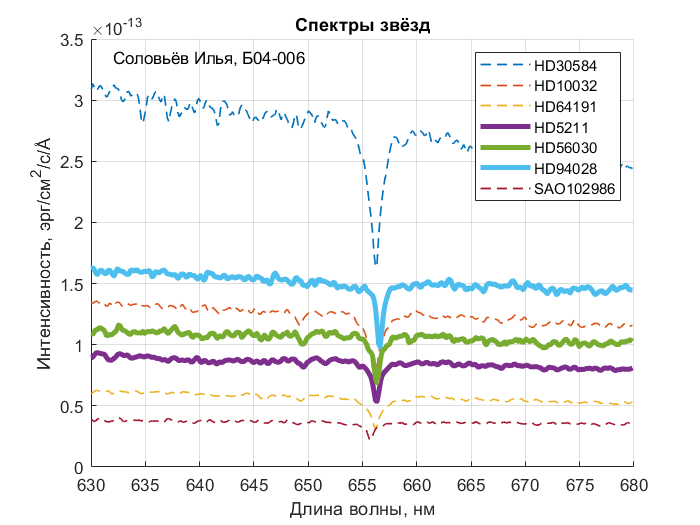

close all
clear variables
spectra = importdata('spectra.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');
starNames = importdata('star_names.csv');
lambdaPr = 656.28;
speedOfLight = 299792.458;
nObs = size(spectra, 1);
nSts = size(starNames, 1);
lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';
[sHa, idx] = min(spectra);
lambdaHa = lambda(idx);
%z>0 - red, z<0 - blue
z = (lambdaHa/lambdaPr) - 1;
speed = z * speedOfLight;
movaway = starNames(speed>0);
fg1 = figure;
hold on;
for i = 1:nSts
if speed(i)>0
plot(lambda, spectra(:,i), 'LineWidth', 3);
else
plot(lambda, spectra(:,i), "--", 'LineWidth', 1);
end
end
hold off;
set(fg1, 'visible', 'on');
xlabel('Длина волны, нм');
ylabel(['Интенсивность, эрг/см^2/с/', char(197)]);
title('Спектры звёзд');
legend(starNames);
text(lambdaStart + 2, max(spectra(:, 1)*1.07), 'Соловьёв Илья, Б04-006')
grid on;
saveas(fg1, 'spectraSts.png')